% Read the table into MATLAB
ICPMS_42 = readtable('S4-2_Simplified.csv');
% Set a text vector for the labels on the X-axis 
elemental_symbols = {'Li', 'Na', 'Mg', 'Al', 'P', 'K', 'Ca', 'Sc', 'Ti', 'Cr', 'Mn', 'Fe', 'Ni', 'Cu', 'Zn', 'Ge', 'Rb', 'Sr', 'Y', 'Zr', 'Nb', 'Ba', 'La', 'Ce', 'Pr', 'Nd', 'Sm', 'Eu', 'Gd', 'Tb', 'Dy', 'Ho', 'Er', 'Tm', 'Yb', 'Lu', 'Hf', 'U'};
% Some blank cells in data, standardize all blanks to NaN
ICPMS_42_clean = standardizeMissing(ICPMS_42, '');
% Create data vectors extracting rows from table to convert to array
%S42_1 = ICPMS_42_clean(58,:);
%Site1 = table2array(S42_1);
S42_AVG_1 = ICPMS_42_clean(61,:);
AVG_1 = table2array(S42_AVG_1);
S42_AVG_2 = ICPMS_42_clean(63,:);
AVG_2 = table2array(S42_AVG_2);
S42_AVG = ICPMS_42_clean(59,:);
AVG = table2array(S42_AVG);
%Remove outliers 
Site1 = rmoutliers(AVG_1)

Site1 =     3.7296    0.0197    4.1682    1.0170    4.2035   55.2737   20.1710    4.4578   91.9483   23.7269    2.0512    2.3996    5.3590    5.4213    3.5148    6.6956   64.6204    8.0817   91.1171   56.1188  162.3977   33.5882   51.2385   55.8426   34.8401  120.1929   35.6101  102.7492   59.4736   93.7914   85.4576  129.6059   97.3019   51.8675   75.9497   75.0517   69.0751   50.3369


Site2 = rmoutliers(AVG_2)

Site2 =     7.4555    1.2605    7.4863    5.1610  446.2676   95.4656   68.2167    4.7619  120.8690   32.6528    6.2796    6.8888   13.2131    1.2222   11.0019    5.8248  109.7491   50.1988  379.3601  113.9350  169.8585  105.4951  424.1985   32.4852  192.1863   29.7447  343.1667  107.1649   84.5151   70.8192  249.4914  115.7718  377.2749


%Site3 = rmoutliers(Site3)
AVG = rmoutliers(AVG)

AVG =     5.5925    0.6401    5.8273    3.0890  193.6595   72.4988   44.1938    4.6099  106.4087   28.1899    4.1654    4.6442    9.2860    3.3218    7.2584    6.4779   87.1848   29.1402  235.2386   85.0269  166.1281   69.5416  240.0205  299.2799  362.1530   34.5684   86.0161   80.9820  195.9043  119.9883   93.0396   55.6578  133.7970   89.0880  213.8059


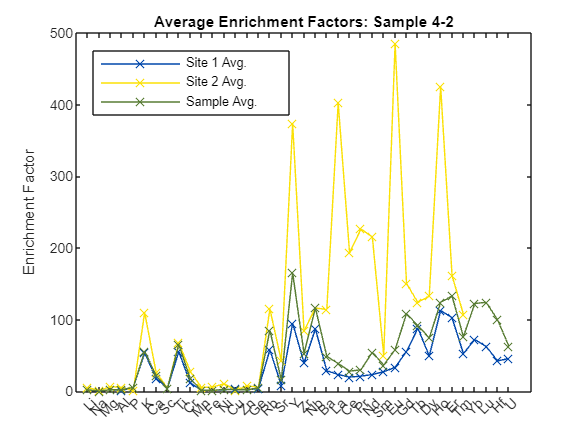

% Plot data, set large figure size 
figure('Position', [100, 100, 800, 600])
%Plot and then hold to overprint with other sites
%plot(Site1, 'x-', Color='#0147AB') 
plot(Site1, 'x-', Color='#8E1E1D') 
hold on;
plot(Site2, 'x-', Color='#FBE106')
plot(AVG, 'x-', Color='#597D35')
% Legend labeled with each subsite 
legend('Site 1 Avg.', 'Site 2 Avg.', 'Sample Avg.', Location='northwest')
% Set x axis to remain constant with ticks and symbols
% This prevents the missing data points from mismatching with the x axis 
xticks(1:length(elemental_symbols));
xticklabels(elemental_symbols);
% Angle element labels
xtickangle(45); 
set(gca, 'FontSize', 7);
% Labels
ylabel('Enrichment Factor')
title('Average Enrichment Factors: Sample 4-2')
hold off;

% Color Notes #0147AB - Blue ; #FBE106 - Yellow ; #597D35 - Green 
% #8E1E1D - Red